load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\true1_assumption1\rfdata.mat");
figure;
openfig('H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\true1_assumption1\rfdata_whole.fig');
xlim([35.3 68.3])
ylim([1 867])
min_reference = min(reference_point) - 100;
max_reference = min(reference_point) + 500 - 1;
mask_rfdata = zeros(size(focused_rfdata));
mask_rfdata(min_reference:max_reference,41:60) = 1;
masked_rfdata = mask_rfdata .* focused_rfdata;
figure;
imagesc(masked_rfdata);
hold on
scatter(41:60,reference_point(41:60),2,'red');
xlabel('receiver[ch]');load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\true1_assumption1\rfdata.mat");
figure;
openfig('H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\true1_assumption1\rfdata_whole.fig');
xlim([35.3 68.3])
ylim([1 867])
min_reference = min(reference_point) - 100;
max_reference = min(reference_point) + 500 - 1;
mask_rfdata = zeros(size(focused_rfdata));
mask_rfdata(min_reference:max_reference,41:60) = 1;
masked_rfdata = mask_rfdata .* focused_rfdata;
figure;
imagesc(masked_rfdata);
hold on
scatter(41:60,reference_point(41:60),2,'red');
xlabel('receiver[ch]');
ylabel('time[sample]');
axis square;
axis tight;
xlim([40 61])
ylim([min_reference max_reference])
colormap(bone);
colorbar;
caxis([min(min(masked_rfdata)) max(max(masked_rfdata))])
figure;
plot(masked_rfdata(:,41));
hold on
plot(masked_rfdata(:,42));
plot(masked_rfdata(:,43));
displacement = zeros(20,1);
curvature = zeros(20,1);
for ii = 41:60-1
    [acor,lag] = xcorr(masked_rfdata(:,ii+1),masked_rfdata(:,ii),'coeff');
    [~,I] = max(abs(acor));
    displacement(ii-40+1) = lag(I);
end
for ii = 1:20
    curvature(ii) = sum(displacement(1:ii));
end
figure;
plot(curvature);
hold on
plot(reference_point(41:60)-max(reference_point(41:60)),'.');
ylabel('time[sample]');
axis square;
axis tight;
xlim([40 61])
ylim([min_reference max_reference])
colormap(bone);
colorbar;
caxis([min(min(masked_rfdata)) max(max(masked_rfdata))])
figure;
plot(masked_rfdata(:,41));
hold on
plot(masked_rfdata(:,42));
plot(masked_rfdata(:,43));
displacement = zeros(20,1);
curvature = zeros(20,1);
for ii = 41:60-1
    [acor,lag] = xcorr(masked_rfdata(:,ii+1),masked_rfdata(:,ii),'coeff');
    [~,I] = max(abs(acor));
    displacement(ii-40+1) = lag(I);
end
for ii = 1:20
    curvature(ii) = sum(displacement(1:ii));
end
figure;
plot(41:60,curvature*kgrid.dt*1e9);
hold on
plot(41:60,reference_point(41:60)*kgrid.dt*1e9-max(reference_point(41:60))*kgrid.dt*1e9,'.');
xlabel('受信ch')
ylabel('時刻[ns]')
exportfig("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\curve_cc1_1_layer",'png',[250 200]);

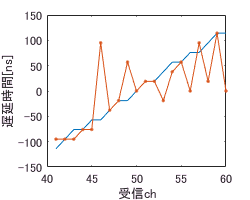

load("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\lateral0.0mm\true1_assumption1\rfdata.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL2.0_pure\kgrid.mat")
figure;
diff_a = diff(reference_point);
plot(41:60,diff_a(41:60)*kgrid.dt*1e9);
hold on
plot(41:60,displacement_tmp(41:60)*kgrid.dt*1e9,'.-');
xlabel('受信ch')
ylabel('遅延時間[ns]')
exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\delay_cc1_1_case26",'png',[250 200]);

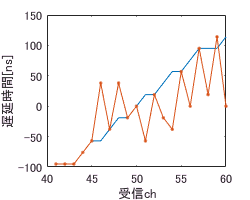

load("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\lateral0.0mm\true1_assumption11\rfdata.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL2.0_pure\kgrid.mat")
figure;
diff_a = diff(reference_point);
plot(41:60,diff_a(41:60)*kgrid.dt*1e9);
hold on
plot(41:60,displacement_tmp(41:60)*kgrid.dt*1e9,'.-');
xlabel('受信ch')
ylabel('遅延時間[ns]')
exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\delay_cc1_11_lateral0.0_case26",'png',[250 200]);

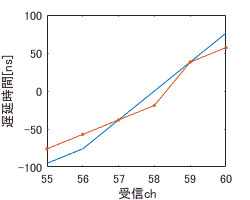

load("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\lateral3.2mm\true1_assumption1\rfdata.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL2.0_pure\kgrid.mat")
figure;
diff_a = diff(reference_point);
plot(55:60,diff_a(55:60)*kgrid.dt*1e9);
hold on
plot(55:60,displacement_tmp(55:60)*kgrid.dt*1e9,'.-');
xlabel('受信ch')
ylabel('遅延時間[ns]')
exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\delay_cc1_1_lateral3.2_case26",'png',[250 200]);

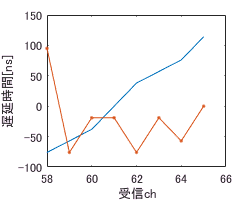

load("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\lateral4.4mm\true1_assumption2\rfdata.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL2.0_pure\kgrid.mat")
figure;
diff_a = diff(reference_point);
plot(58:65,diff_a(58:65)*kgrid.dt*1e9);
hold on
plot(58:65,displacement_tmp(58:65)*kgrid.dt*1e9,'.-');
xlabel('受信ch')
ylabel('遅延時間[ns]')
exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\delay_cc1_2_lateral4.4_case26",'png',[250 200]);

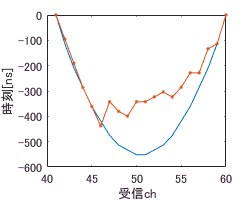

for ii = 1:20
    curvature(ii) = sum(displacement_tmp(40:ii+40-1));
end
figure;
plot(41:60,reference_point(41:60)*kgrid.dt*1e9-max(reference_point(41:60)*kgrid.dt*1e9));
hold on
plot(41:60,curvature*kgrid.dt*1e9,'.-');


xlabel('受信ch')
ylabel('時刻[ns]')
exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\curve_cc1_1_case26",'png',[250 200]);

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\true1_assumption1\rfdata.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL2.0_pure\kgrid.mat")
figure;
diff_a = diff(reference_point);
plot(41:60,diff_a(41:60)*kgrid.dt*1e9);
hold on
a = displacement*kgrid.dt*1e9;
plot(41:59,a(2:end),'.');
xlabel('受信ch')
ylabel('遅延時間[ns]')
exportfig("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\delay_cc1_1_layer",'png',[250 200]);


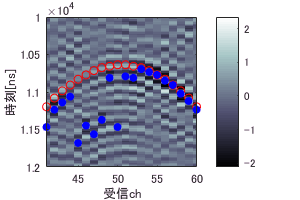

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case26\true1_assumption1\rfdata.mat")

figure;
x = 1:100;
y = kgrid.dt*(1:5263)*1e9;
imagesc(x,y,focused_rfdata)
axis square;
axis tight;
colormap(bone);
colorbar;
xlim([41 60])
caxis([min(min(focused_rfdata_masked)) max(max(focused_rfdata_masked))])
xlabel('受信ch')
ylabel('時刻[ns]')
ylim([0.00001*1e9 0.0000120*1e9])
hold on
scatter(41:60,reference_point(41:60)*kgrid.dt*1e9,'red');
scatter(41:60,point_max_in_mask(41:60)*kgrid.dt*1e9,'blue','filled');
exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\delay1_1_case26",'png',[300 200]);

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\true1_assumption1\rfdata.mat")

figure;
x = 1:100;
y = kgrid.dt*(1:5263)*1e9;
imagesc(x,y,focused_rfdata)
axis square;
axis tight;
colormap(bone);
colorbar;
xlim([41 60])
caxis([min(min(focused_rfdata_masked)) max(max(focused_rfdata_masked))])
xlabel('受信ch')
ylabel('時刻[ns]')
ylim([0.00001*1e9 0.0000120*1e9])
hold on
scatter(41:60,reference_point(41:60)*kgrid.dt*1e9,'red');
scatter(41:60,point_max_in_mask(41:60)*kgrid.dt*1e9,'blue','filled');
exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\delay1_1_layer",'png',[300 200]);

load("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_25_case26\total_result.mat");

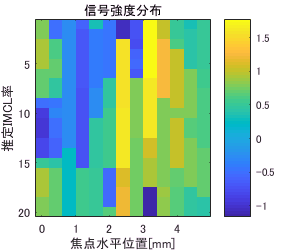


figure;
imagesc(lateral_range_min:element_pitch*1e3:lateral_range_max*1e3,1:20,permute(max_signal(:,1,:),[1 3 2]));
colorbar
xlabel('焦点水平位置[mm]')
ylabel('推定IMCL率')
title('信号強度分布')
exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\intensity_medium1",'png',[300 250]);

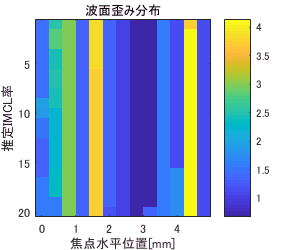

imagesc(lateral_range_min:element_pitch*1e3:lateral_range_max*1e3,1:20,permute(error_wavefront(:,1,:),[1 3 2]));
colorbar
xlabel('焦点水平位置[mm]')
ylabel('推定IMCL率')
title('波面歪み分布')
exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\error_wavefront_medium1",'png',[300 250]);

openfig('H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\lateral0.0mm\true1_assumption11\rfdata_masked.fig')

ans =   Figure (202) のプロパティ:

      Number: 202
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  すべてのプロパティ を表示


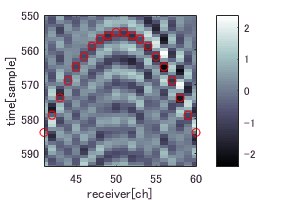

exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\delay1_11_lateral0.0_case26",'png',[300 200]);

openfig('H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\lateral3.2mm\true1_assumption1\rfdata_masked.fig')

ans =   Figure (204) のプロパティ:

      Number: 204
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  すべてのプロパティ を表示


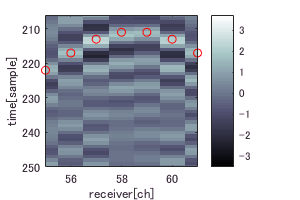

exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\delay1_1_latral3.2_case26",'png',[300 200]);

openfig('H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\lateral4.4mm\true1_assumption2\rfdata_masked.fig')

ans =   Figure (218) のプロパティ:

      Number: 218
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  すべてのプロパティ を表示


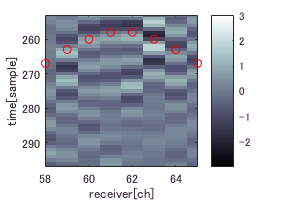

exportfig("H:\result\2018_11_25_IMCL_estimation_boundary_search_re\2018_11_27_case26\figure\delay1_2_latral4.4_case26",'png',[300 200]);